%% Roshan Jaiswal-Ferri
%Section - 01 
%Aero 355 Final: 3/16/25

%% Workspace Prep

%warning off
format long     %Allows for more accurate decimals
close all;      %Clears all
clear all;      %Clears Workspace
clc;            %Clears Command Window

# Question 2:

Calculate and graph the interplanetary MM background flux at 1AU from the Sun for objects ranging in masses from 10^-16 to 1 g.  Please look at your graph.  Do you need a semilog or a loglog plot instead of just plot?

Compare that (add to the same graph) with the flux over the same size range for an Earth orbiting satellite’s ram facing surface at an  altitude of 300 km.

Also, please give specific answers based on these graphs for the next three questions.

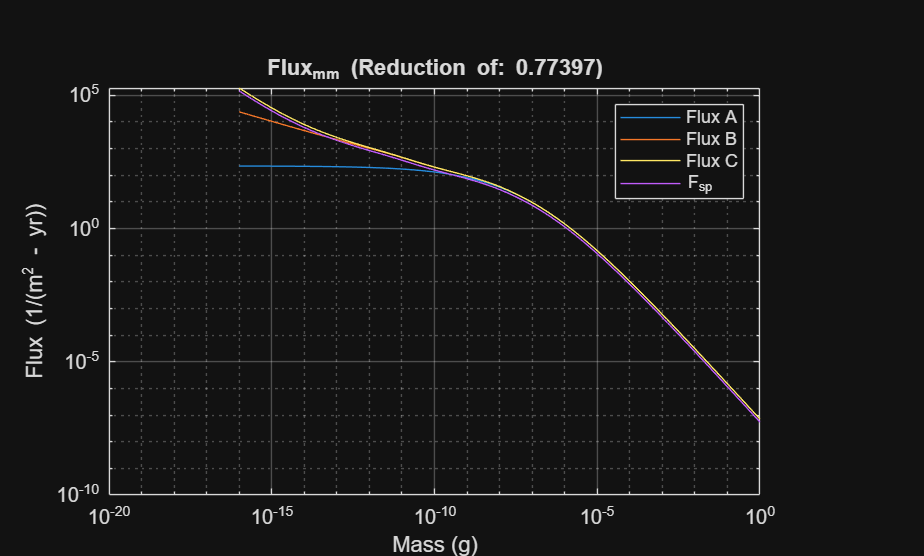

Re = 6378;
mm1 = linspace(10^-16,10^-13,1000000);
mm2 = linspace(10^-13,10^-10,1000000);
mm3 = linspace(10^-10,10^-6,1000000);
mm4 = linspace(10^-6,10^-3,1000000);
mm5 = linspace(10^-3,1,1000000);
mm = [mm1 mm2 mm3 mm4 mm5];


% [~, pos1] = min(abs(mm - 10^-14));
% m1 = mm(1:pos1);
% [~, pos2] = min(abs(mm - 10^-9));
% m2 = mm(pos1:pos2);                          this stuff is not right
% m3 = mm(pos2:end);
% A = (15 + (2.2*10^3)*m3.^(0.306)).^(-4.38); %for 10^(-9) g < m < 1 g
% B = 1.3*10.^(-9)*(m2 + (10.^11*m2.^2) + (10.^27*m2.^4)).^(-0.36); %Specific for 10^(-14) g < m < 10^(-9) g
% C = 1.3*10.^(-16)*(m1 + (10.^6)*m1.^2).^(-0.85) %for 10^(-18) g < m < 10^(-14) g

A = (15 + (2.2*10^3)*mm.^(0.306)).^(-4.38); %for 10^(-9) g < m < 1 g
B = 1.3*10.^(-9)*(mm + (10.^11*mm.^2) + (10.^27*mm.^4)).^(-0.36); %Specific for 10^(-14) g < m < 10^(-9) g
C = 1.3*10.^(-16)*(mm + (10.^6)*mm.^2).^(-0.85); %for 10^(-18) g < m < 10^(-14) g

b_fluxA = (3.15576e7)*(A);
b_fluxB = (3.15576e7)*(A+B);
b_fluxC = (3.15576e7)*(A+B+C);

fgrav = 1 + (Re+100)/(Re+300);

n = asin((Re+100)/(Re+300)); %assuming radians
fshield = (1+cos(n))/2; %assuming radians

fdist = (1.8+3*sqrt(1-((Re+100)/(Re+300))^2))/4;

Fsp = b_fluxC*fgrav*fshield*fdist; %fdist calculated for ram direction

reduction = fgrav*fshield*fdist;

figure('Name','Flux_mm')
loglog(mm,b_fluxA)
hold on
grid on
loglog(mm,b_fluxB)
loglog(mm,b_fluxC)
loglog(mm,Fsp)
xlabel('Mass (g)')
ylabel('Flux (1/(m^2 - yr))')
title(['Flux_m_m (Reduction of: ', num2str(reduction),')'])
legend('Flux A', 'Flux B', 'Flux C', 'F_s_p')

# Question 5

From your plot, give the specific flux (1/(m2*yr)) value for MM mass of  10^-6 g and greater.  Give results to three decimal places. 

%% Section

mm = 10^-6;
A = (15 + (2.2*10^3)*mm.^(0.306)).^(-4.38); %for 10^(-9) g < m < 1 g
fluxA = (3.15576e7)*(A);
disp(num2str(fluxA));

1.4843


# Question 6

Calculate and graph the orbital debris (human-made) flux for sizes ranging from 10^-6 to 10^3 cm for objects at an altitude of 300 km, at inclination of 52°, at an S (F10.7) of 100, with k = 1, for the year 2024.  Do you need a semilog  or a loglog plot instead of just a plot for the graph? The values for each number needs to be readable.  Use d = logspace(-6,3) [cm] for the distribution of your diameters. 

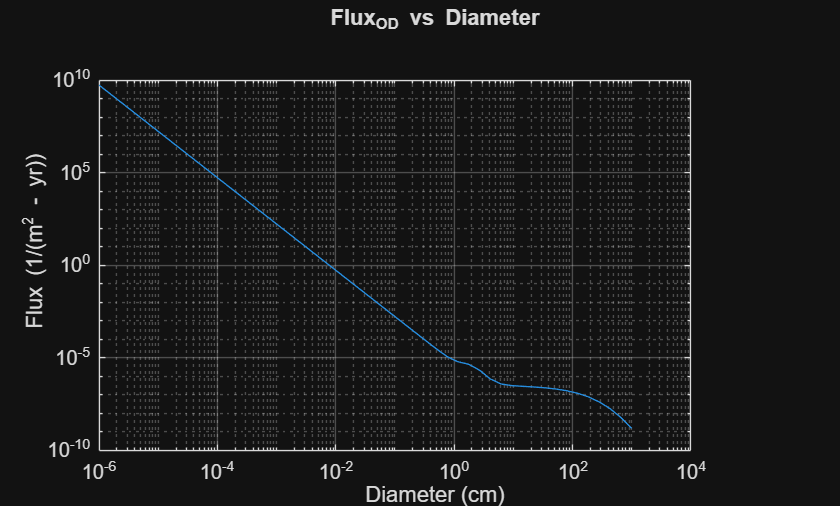

%% Section

d = logspace(-6,3);
k = 1;
S = 100;
q = 0.02;
qp = 0.04;
t = 2024 - 2011;
p = 0.05;

H = (10.^(exp(-((log(d)-0.78)/0.637).^2))).^0.5;

phi1 = 10^((300/200) - (S/140) - 1.5);
phi = phi1/(phi1+1);

psi = 1.03; %table lookup for 52deg

f1 = (1.22*10^-5)*d.^-2.5;
f2 = (8.1*10^10)*(d+700).^-6;
g1 = ((1+q)^23)*((1+qp)^t);
g2 = 1 + p*(2024-1988);

Fod = k.*H.*phi.*psi.*(f1.*g1 + f2.*g2);

figure('Name','Flux_o_d vs Diameter')
loglog(d,Fod)
hold on
grid on
xlabel('Diameter (cm)')
ylabel('Flux (1/(m^2 - yr))')
title('Flux_O_D vs Diameter')

# Question 8

From your plot, what is the specific flux (1/(m2yr)) for 10^-3 cm and greater.  Please give your result with three decimal places. 

%% Section

d = 10^-3;
k = 1;
S = 100;
q = 0.02;
qp = 0.04;
t = 2024 - 2011;
p = 0.05;

H = (10.^(exp(-((log(d)-0.78)/0.637).^2))).^0.5;

phi1 = 10^((300/200) - (S/140) - 1.5);
phi = phi1/(phi1+1);

psi = 1.03; %table lookup for 52deg

f1 = (1.22*10^-5)*d.^-2.5;
f2 = (8.1*10^10)*(d+700).^-6;
g1 = ((1+q)^23)*((1+qp)^t);
g2 = 1 + p*(2024-1988);

Fod = k.*H.*phi.*psi.*(f1.*g1 + f2.*g2);
disp(num2str(Fod));

168.8429


# Question 9

For that same size regime (10^-3 cm and greater), what is the flux if you want to launch in 2030? Please give your results with three decimal places.   

%% Section

d = 10^-3;
k = 1;
S = 100;
q = 0.02;
qp = 0.04;
t = 2030 - 2011;
p = 0.05;

H = (10.^(exp(-((log(d)-0.78)/0.637).^2))).^0.5;

phi1 = 10^((300/200) - (S/140) - 1.5);
phi = phi1/(phi1+1);

psi = 1.03; %table lookup for 52deg

f1 = (1.22*10^-5)*d.^-2.5;
f2 = (8.1*10^10)*(d+700).^-6;
g1 = ((1+q)^23)*((1+qp)^t);
g2 = 1 + p*(2030-1988);

Fod = k.*H.*phi.*psi.*(f1.*g1 + f2.*g2);
disp(num2str(Fod));

213.6402


# Question 10

Give the specific number for crater diameter for an aluminum target (K or C=0.351) for a 1 cm particle traveling 10 km/s with density of 3.5 g/cm3.  Give your results in cm with two decimal places.

%% Section

k = 0.351;
dpart = 1;
rho = 3.5;
v = 10;
dimpact = k*(dpart^1.056)*(rho^0.579)*(v^(2/3));
disp(num2str(dimpact));

3.365


# Question 11

Give the specific number for shield thickness (critial) for aluminum (K or C=0.351)for a 1 g particle traveling 10 km/s with density of 3.5 g/cm3.  Give your results in cm with two decimal places.      

%% Section

k = 0.351;
mass = 1;
rho = 3.5;
v = 10;
tcrit = k*(rho^(1/6))*(mass^0.352)*(v^0.875);
disp(num2str(tcrit));

3.2433


# Question 12

For this problem, you will input data  in two parts using the same givens.  For this problem, please only  include the flux due to orbital debris. 

The tiles on the Space Shuttle were  used for thermal control and were called TPS.  The minimum diameter of  an impactor for penetration for TPS is 3 mm. The size for critical  failure is 8 mm.  Assume the Shuttle is flying at the same orbit and  time frame as the flux calculation problem that is also in this exam:  300 km, at inclination of 52°, at an S (F10.7) of 100, with k = 1, for  the year 2024.  

(a) Calculate the number of impacts for a 735 m2 area of TPS (belly of the space shuttle). Using that number, what is  the PNCF for the TPS over a 1 year period.  Give the result as #.####

%% Section

d = 0.8;
k = 1;
S = 100;
q = 0.02;
qp = 0.04;
t = 2024 - 2011;
p = 0.05;

H = (10.^(exp(-((log(d)-0.78)/0.637).^2))).^0.5;

phi1 = 10^((300/200) - (S/140) - 1.5);
phi = phi1/(phi1+1);

psi = 1.03; %table lookup for 52deg

f1 = (1.22*10^-5)*d.^-2.5;
f2 = (8.1*10^10)*(d+700).^-6;
g1 = ((1+q)^23)*((1+qp)^t);
g2 = 1 + p*(2024-1988);

Fod = k.*H.*phi.*psi.*(f1.*g1 + f2.*g2);


A = 735;
T = 1;
Fmmod = Fod; %adding the total flux of 3mm and greater, adding values from Fmm makes PNCF go to zero?
n = Fmmod*A*T;
PNCF = exp(-n);
disp(num2str(PNCF));

0.99222


# Question 13

(b) Calculate the number of impacts for a 735 m2 area of TPS (belly of the space shuttle) using the penetration number  shown above. Using that flux, calculate PNP for the TPS over a 1 year  period. Give the result as #.####

%% Section

d = 0.3; %making any hole
k = 1;
S = 100;
q = 0.02;
qp = 0.04;
t = 2024 - 2011;
p = 0.05;

H = (10.^(exp(-((log(d)-0.78)/0.637).^2))).^0.5;

phi1 = 10^((300/200) - (S/140) - 1.5);
phi = phi1/(phi1+1);

psi = 1.03; %table lookup for 52deg

f1 = (1.22*10^-5)*d.^-2.5;
f2 = (8.1*10^10)*(d+700).^-6;
g1 = ((1+q)^23)*((1+qp)^t);
g2 = 1 + p*(2024-1988);

Fod = k.*H.*phi.*psi.*(f1.*g1 + f2.*g2);


A = 735;
T = 1;
Fmmod = Fod; %adding the total flux of 3mm and greater, adding values from Fmm makes PNCF go to zero?
n = Fmmod*A*T;
PNP = exp(-n); 
disp(num2str(PNP));

0.92325
